## Group assignment 5 - ting ting

clear;

II)

You need testdata (virtuel measurements) for test or simulation of a flight simulator. The testdata should simulate the altitude of a plane and are supposed to be Rayleigh distributed:

1.Find the cdf for the Rayleigh distribution fx(x).

x = [0:0.01:2]

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


p = raylpdf(x, 0.5)

p =          0    0.0400    0.0799    0.1198    0.1595    0.1990    0.2383    0.2773    0.3159    0.3542    0.3921    0.4295    0.4664    0.5027    0.5385    0.5736    0.6081    0.6418    0.6748    0.7071    0.7385    0.7691    0.7988    0.8276    0.8555    0.8825    0.9085    0.9335    0.9575    0.9804    1.0023    1.0232    1.0430    1.0617    1.0793    1.0958    1.1112    1.1255    1.1387    1.1508    1.1618    1.1717    1.1806    1.1883    1.1950    1.2006    1.2051    1.2086    1.2111    1.2126


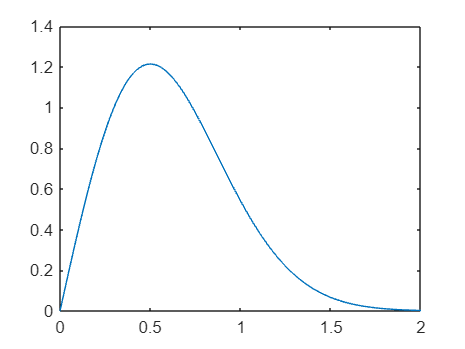

figure;
plot(x,p);

z = zeros(1,length(p));
for i=1:length(p)
    z(i) = sum(p(1:i));
end
z

z =          0    0.0400    0.1199    0.2397    0.3992    0.5982    0.8365    1.1138    1.4297    1.7839    2.1760    2.6055    3.0718    3.5745    4.1130    4.6866    5.2947    5.9365    6.6113    7.3184    8.0569    8.8259    9.6248   10.4524   11.3079   12.1904   13.0989   14.0324   14.9899   15.9703   16.9726   17.9958   19.0387   20.1004   21.1797   22.2754   23.3866   24.5122   25.6509   26.8017   27.9636   29.1353   30.3159   31.5042   32.6991   33.8997   35.1048   36.3134   37.5245   38.7371


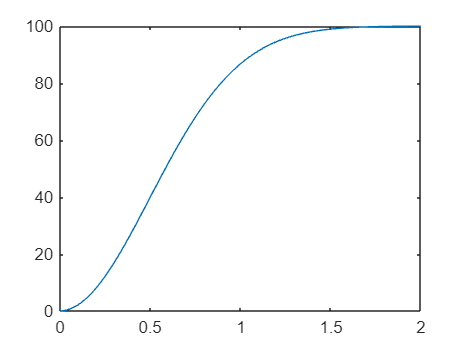

figure;
plot(x,z);

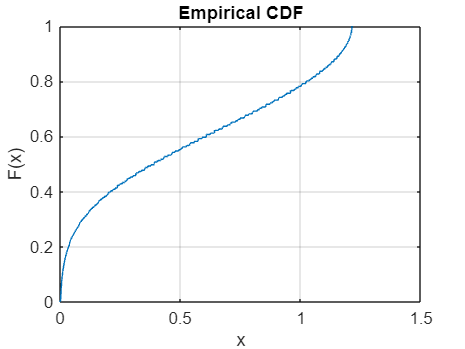

Unrecognized function or variable 'sig'.


%cdfplot(p,x);

2.Find the inverse of the Rayleigh cdf (ie. x as a function of 푦=퐹푋(푥)).

3. Make a Matlab programme that makes 10000 random Rayleigh distributed test data with 휎=7.

4.Make a scatter-plot of the testdata.

5.Make a histogram of the data. Does it look like a Rayleigh distribution?

1)